Añadimos el filtro de prénfasis a cada una de las señales muestreadas

Filter_5 = cellfun(@(signal) filter([1 -0.95],1,signal) ,Uno,'UniformOutput',false);

Obtenemos los bloques de 512 y las agrupamos en una sola matriz de N x 512

Blocks_5 = getBlocksAllSamples(Filter_5);

r_5 = Correlation.AutoCorrs(Blocks_5,13);

C1 = 1/length(r_5) *sum(r_5);
[idx, C] = CuantizadorVectorial.LindeBuzoGray(C1,4,5 * r_5)

nCentroides =     0.0570    0.0413    0.0273    0.0218    0.0106    0.0041   -0.0020   -0.0101   -0.0107   -0.0047   -0.0017   -0.0031   -0.0015
    0.0570    0.0413    0.0273    0.0218    0.0106    0.0041   -0.0020   -0.0101   -0.0107   -0.0047   -0.0017   -0.0031   -0.0015


La primera distancia: 


distances =     0.0098    0.0098
    0.0110    0.0110
    0.0105    0.0105
    0.0068    0.0068
    0.0087    0.0087
    0.0132    0.0132
    0.0133    0.0133
    0.0110    0.0110
    0.0113    0.0113
    0.0108    0.0108


El número de muestras por grupo


samplesPerCent =    562
   131


distances =     0.0097    0.0123
    0.0108    0.0136
    0.0103    0.0131
    0.0068    0.0082
    0.0086    0.0101
    0.0131    0.0158
    0.0133    0.0156
    0.0109    0.0129
    0.0111    0.0133
    0.0106    0.0127


El número de muestras por grupo


samplesPerCent =    633
    60


distances =     0.0098    0.0107
    0.0109    0.0123
    0.0105    0.0114
    0.0068    0.0077
    0.0084    0.0118
    0.0130    0.0162
    0.0131    0.0159
    0.0111    0.0111
    0.0114    0.0111
    0.0108    0.0106


El número de muestras por grupo


samplesPerCent =    508
   185


distances =     0.0084    0.0139
    0.0093    0.0157
    0.0089    0.0149
    0.0059    0.0098
    0.0076    0.0128
    0.0114    0.0191
    0.0115    0.0190
    0.0097    0.0147
    0.0100    0.0150
    0.0095    0.0143


El número de muestras por grupo


samplesPerCent =    693
     0


distances =     0.0098       NaN
    0.0110       NaN
    0.0105       NaN
    0.0068       NaN
    0.0087       NaN
    0.0132       NaN
    0.0133       NaN
    0.0110       NaN
    0.0113       NaN
    0.0108       NaN


El número de muestras por grupo


samplesPerCent =    693
     0


distances =     0.0098       NaN
    0.0110       NaN
    0.0105       NaN
    0.0068       NaN
    0.0087       NaN
    0.0132       NaN
    0.0133       NaN
    0.0110       NaN
    0.0113       NaN
    0.0108       NaN


nCentroides =     0.2850    0.2065    0.1364    0.1091    0.0528    0.0204   -0.0098   -0.0503   -0.0534   -0.0234   -0.0083   -0.0155   -0.0073
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.2850    0.2065    0.1364    0.1091    0.0528    0.0204   -0.0098   -0.0503   -0.0534   -0.0234   -0.0083   -0.0155   -0.0073
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


La primera distancia: 


distances =     0.0098       NaN    0.0098       NaN
    0.0110       NaN    0.0110       NaN
    0.0105       NaN    0.0105       NaN
    0.0068       NaN    0.0068       NaN
    0.0087       NaN    0.0087       NaN
    0.0132       NaN    0.0132       NaN
    0.0133       NaN    0.0133       NaN
    0.0110       NaN    0.0110       NaN
    0.0113       NaN    0.0113       NaN
    0.0108       NaN    0.0108       NaN


El número de muestras por grupo


samplesPerCent =     21
     0
   672
     0


distances =     0.0137       NaN    0.0099       NaN
    0.0146       NaN    0.0111       NaN
    0.0142       NaN    0.0106       NaN
    0.0088       NaN    0.0069       NaN
    0.0096       NaN    0.0088       NaN
    0.0162       NaN    0.0134       NaN
    0.0166       NaN    0.0135       NaN
    0.0163       NaN    0.0111       NaN
    0.0168       NaN    0.0114       NaN
    0.0164       NaN    0.0108       NaN


El número de muestras por grupo


samplesPerCent =     34
     0
   659
     0


distances =     0.0177       NaN    0.0095       NaN
    0.0198       NaN    0.0106       NaN
    0.0190       NaN    0.0102       NaN
    0.0122       NaN    0.0067       NaN
    0.0152       NaN    0.0085       NaN
    0.0239       NaN    0.0129       NaN
    0.0245       NaN    0.0130       NaN
    0.0215       NaN    0.0107       NaN
    0.0216       NaN    0.0110       NaN
    0.0208       NaN    0.0104       NaN


El número de muestras por grupo


samplesPerCent =     10
     0
   683
     0


distances =     0.0104       NaN    0.0098       NaN
    0.0123       NaN    0.0109       NaN
    0.0109       NaN    0.0105       NaN
    0.0080       NaN    0.0068       NaN
    0.0146       NaN    0.0085       NaN
    0.0183       NaN    0.0131       NaN
    0.0174       NaN    0.0132       NaN
    0.0102       NaN    0.0111       NaN
    0.0100       NaN    0.0113       NaN
    0.0095       NaN    0.0108       NaN


El número de muestras por grupo


samplesPerCent =    247
     0
   446
     0


distances =     0.0118       NaN    0.0089       NaN
    0.0135       NaN    0.0099       NaN
    0.0129       NaN    0.0094       NaN
    0.0085       NaN    0.0062       NaN
    0.0110       NaN    0.0079       NaN
    0.0166       NaN    0.0119       NaN
    0.0164       NaN    0.0120       NaN
    0.0132       NaN    0.0103       NaN
    0.0136       NaN    0.0106       NaN
    0.0128       NaN    0.0101       NaN


El número de muestras por grupo


samplesPerCent =    150
     0
   543
     0


distances =     0.0064       NaN    0.0111       NaN
    0.0072       NaN    0.0124       NaN
    0.0067       NaN    0.0119       NaN
    0.0047       NaN    0.0077       NaN
    0.0070       NaN    0.0096       NaN
    0.0097       NaN    0.0147       NaN
    0.0093       NaN    0.0150       NaN
    0.0069       NaN    0.0126       NaN
    0.0071       NaN    0.0129       NaN
    0.0067       NaN    0.0124       NaN


El número de muestras por grupo


samplesPerCent =    693
     0
     0
     0


distances =     0.0098       NaN       NaN       NaN
    0.0110       NaN       NaN       NaN
    0.0105       NaN       NaN       NaN
    0.0068       NaN       NaN       NaN
    0.0087       NaN       NaN       NaN
    0.0132       NaN       NaN       NaN
    0.0133       NaN       NaN       NaN
    0.0110       NaN       NaN       NaN
    0.0113       NaN       NaN       NaN
    0.0108       NaN       NaN       NaN


El número de muestras por grupo


samplesPerCent =    693
     0
     0
     0


distances =     0.0098       NaN       NaN       NaN
    0.0110       NaN       NaN       NaN
    0.0105       NaN       NaN       NaN
    0.0068       NaN       NaN       NaN
    0.0087       NaN       NaN       NaN
    0.0132       NaN       NaN       NaN
    0.0133       NaN       NaN       NaN
    0.0110       NaN       NaN       NaN
    0.0113       NaN       NaN       NaN
    0.0108       NaN       NaN       NaN


idx =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


C =     0.2850    0.2065    0.1364    0.1091    0.0528    0.0204   -0.0098   -0.0503   -0.0534   -0.0234   -0.0083   -0.0155   -0.0073
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


a = Wienner.centPredictors(r_5(30:42,:))

a =     1.0729   -0.5775    0.6795   -0.8033    0.3845   -0.3922    0.4271   -0.3407   -0.0075    0.1106   -0.0545
    1.0224   -0.6755    0.8126   -0.8308    0.5536   -0.6675    0.5595   -0.5548    0.2982   -0.0190   -0.0933
    0.9655   -0.7184    0.8880   -0.8670    0.6743   -0.7525    0.5253   -0.5697    0.3758   -0.0492   -0.1228
    0.9205   -0.7104    0.9783   -0.9661    0.7792   -0.8111    0.5460   -0.6195    0.4522   -0.1657   -0.0305
    0.9482   -0.7342    1.1068   -1.1803    0.9213   -0.9074    0.7300   -0.7412    0.5323   -0.3379    0.0909
    0.8833   -0.5752    0.9869   -1.0764    0.7761   -0.7664    0.5663   -0.6408    0.4719   -0.2463    0.0503
    0.9168   -0.6027    0.8918   -0.9825    0.7418   -0.7116    0.4544   -0.5953    0.4857   -0.2261   -0.0082
    0.9199   -0.6412    0.9015   -0.9995    0.7538   -0.6917    0.4178   -0.5500    0.4261   -0.2495    0.0190
    0.8769   -0.5119    0.9391   -1.1037    0.6744   -0.6757    0.7068   -0.7698    0.4372   -0.3476    0.17

sizeC = size(a);
sizeC(1)

ans = 13

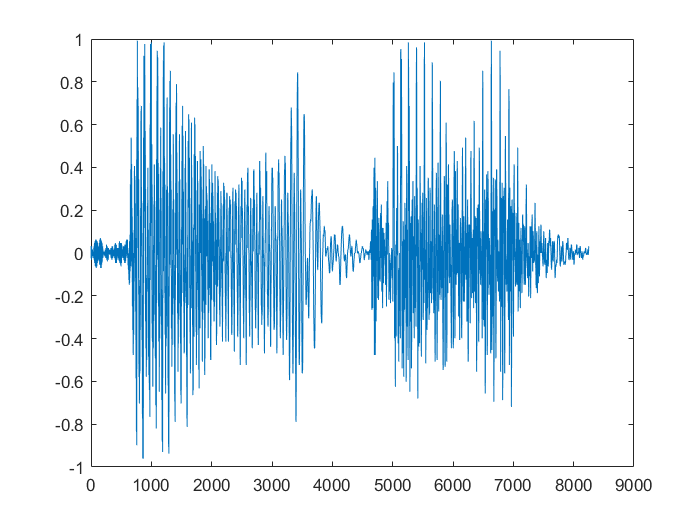

plot(Cinco{1})

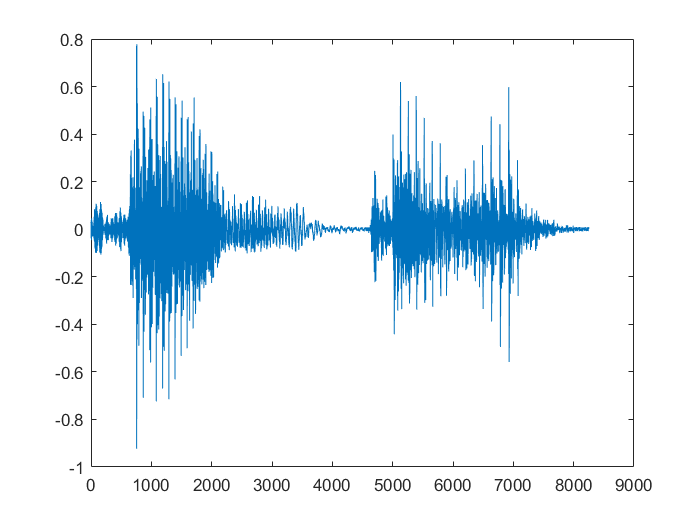

plot(Filter_5{1})

function blocks = getBlocksAllSamples(samples)
    blocks = Hamming.getBlocks(samples{1});
    for i = [2:length(samples)]
            blocks = [blocks; Hamming.getBlocks(samples{i})];
    end
end


% close all
% %L = 64; wvtool(hamming(L))
% %wvtool(fir1(1024,[0.001 0.999]))
% a_pe = 4 * filter([1 -0.95], 1, a);
% o_pe = 4 * filter([1 -0.95], 1, o);
% s_pe = 4 * filter([1 -0.95], 1, s);
% p_pe = 4 * filter([1 -0.95], 1, p);
% pasa_pe = 4 * filter([1 -0.95], 1, n_pasa);
% paso_pe = 4 * filter([1 -0.95], 1, n_paso);
% 
% a_blocks = getBlocks(a_pe);
% o_blocks = getBlocks(o_pe);
% s_blocks = getBlocks(s_pe);
% p_blocks = getBlocks(p_pe);
% pasa_blocks = getBlocks(pasa_pe);
% paso_blocks = getBlocks(paso_pe);
% 
% plotBlocks(a_blocks, 'Comparación de espectros para señal a(t)')
% plotBlocks(o_blocks, 'Comparación de espectros para señal o(t)')
% plotBlocks(s_blocks, 'Comparación de espectros para señal s(t)')
% plotBlocks(p_blocks, 'Comparación de espectros para señal p(t)')
% 
% pot(n_pasa, 'Potencia para distintos bloques de pasa');
% pot(n_paso, 'Potencia para distintos bloques de paso');
% 
% plotSignalT(a_blocks,a_pe,' a ',8);
% plotSignalT(o_blocks,o_pe,' o ',8);
% plotSignalT(s_blocks,s_pe,' s ',8);
% plotSignalT(p_blocks,p_pe,' p ',2);
% %plotSignalT(pasa_blocks,pasa_pe,' p ',20);